%вычисляем чебышёва n-степени
n = 5;
ch = zeros(1, 3);
ch_0 = 1;
ch_1 = [1, 0];
for i=3:n+1
    ch = conv([2, 0], ch_1) - [[0, 0], ch_0];
    ch_0 = ch_1;
    ch_1 = ch;
end
ch;
ch = ch./2^(n-1)

ch =     1.0000         0   -1.2500         0    0.3125         0



%проверим корни
for k = 1:5
    x_k = cos( ((2*k-1)*pi)/(2*n) )
end

x_k = 0.9511

x_k = 0.5878

x_k = 6.1232e-17

x_k = -0.5878

x_k = -0.9511


r = roots(ch)'

r =          0   -0.9511   -0.5878    0.9511    0.5878


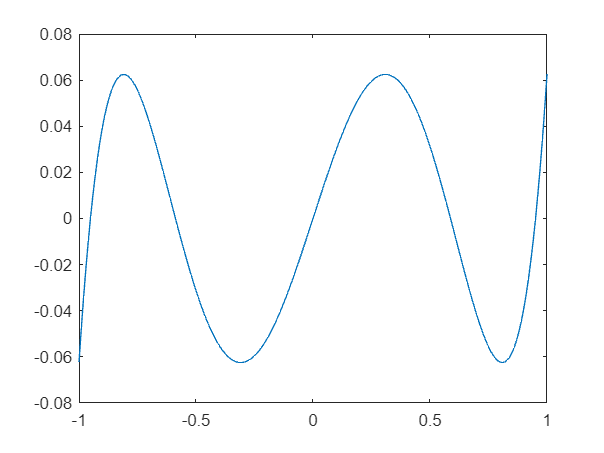


%вычисляю значение в точках, для полинома чебышёва
xx=-1:0.01:1;    
yy = zeros(size(xx));
yy(:) = ch(1);
for i = 2:length(ch)
    yy = xx.* yy + ch(i);
end

plot(xx, yy)


%нахождение прямой вида f = ax + b
A = [-1 1; 1 1];
B = [1; 9];
X = B'/A;

%вычисляю лучшие точки с помощью построенной выше прямой
best_dots = X(1)*r(1) + X(2);
for i = 2:n
    best_dots = [best_dots, X(1)*r(i) + X(2)];
end
best_dots

best_dots =     5.0000    1.1958    2.6489    8.8042    7.3511



x = 1:2:9;
y = sin(x);


L = polyfit(x,y, 4);
best_L = polyfit(best_dots, sin(best_dots), 4);

xx = 1:0.1:9;

plot(xx, polyval(L, xx), 'b', xx, sin(xx), 'r', xx, polyval(best_L, xx)); hold on;
legend('Обычная интерполяция', 'sin(x)', 'Интерполяция с точками Чебышёва', 'Location', 'southwest');

%отклонение
differ = 0;
yy = polyval(best_L, xx);
for i=1:length(xx)
    differ = max(abs(yy(i)-sin(xx(i))), differ);
end
differ

differ = 0.2323

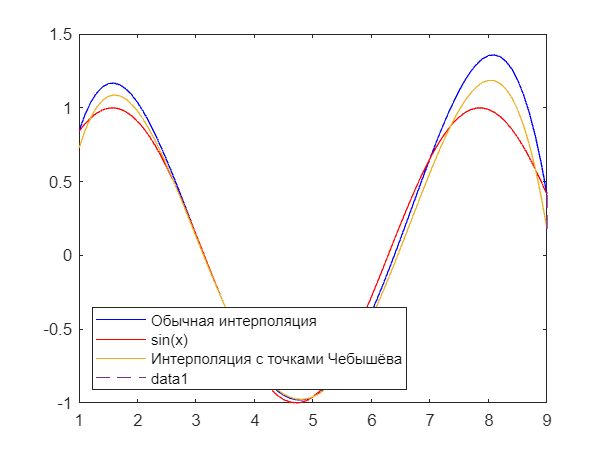


for i=1:length(yy)
    if differ == abs(yy(i)-sin(xx(i)))
        plot([xx(i), xx(i)], [sin(xx(i)), yy(i)], '--');
        break;
    end
end